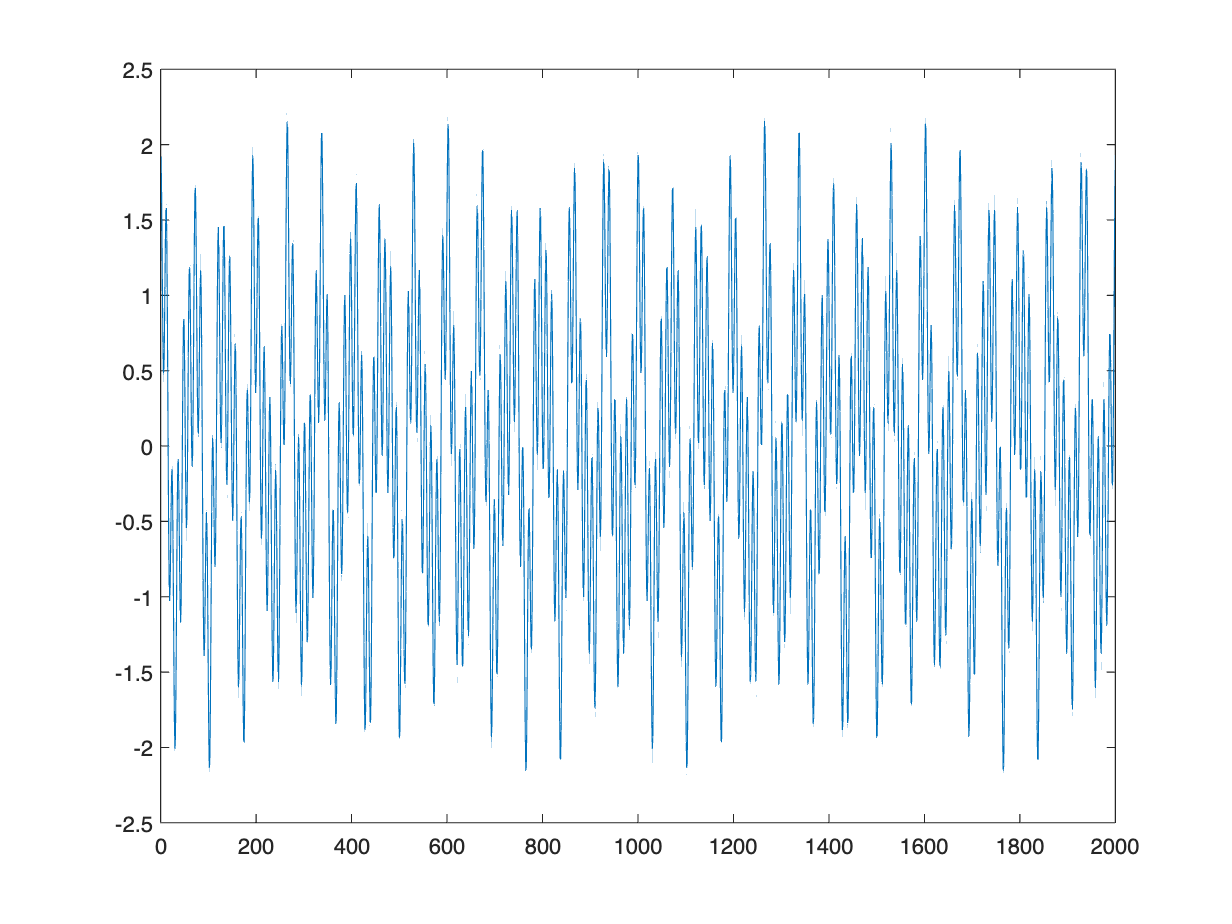

% Parametry systemu
Fs = 1000;     % Częstotliwość próbkowania [Hz]
T = 1/Fs;      % Okres próbkowania [s]
L = 2000;      % Długość sygnału (liczba próbek)
t = (0:L-1)*T; % Podstawa czasu

% Przygotowanie sygnału
N = 3;               % Liczba sinusoid w mieszaninie
A = [1.0   0.4  0.8]; % Amplitudy kolejnych sinusoid
B = [ 15    27   83]; % Częstotliwości kolejnych sygnałów [Hz]
C = [  0 -pi/3 pi/7]; % Przesunięcia fazowe kolejnych sygnałów


x = zeros(size(t));
for i = 1:N
  x = x + A(i) * cos(2 * pi * B(i) * t + C(i));
end

plot(x);

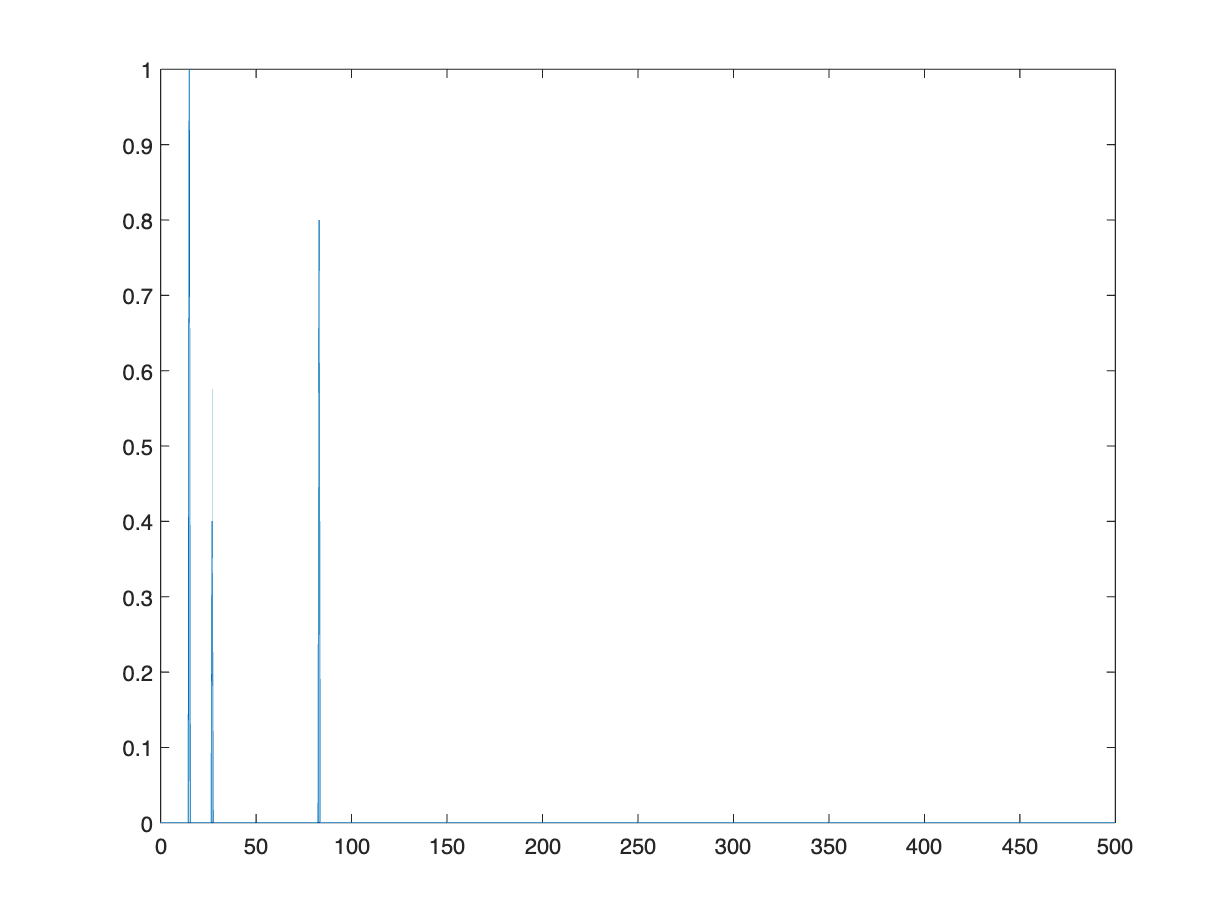


Y = fft(x);     % transformata Fouriera

Amp = abs(Y);     % amplituda sygnału
Amp = Amp/L;        % normalizacja amplitudy

Amp = Amp(1:L/2+1); % wycięcie istotnej części spektrum
Amp(2:end-1) = 2*Amp(2:end-1);

Phi = angle(Y);   % faza sygnału
Phi = Phi(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);        % wykres amplitudowy

[top_values, indices] = maxk(Amp, 3)

top_values =     1.0000    0.8000    0.4000


indices =     31   167    55



f_top_values = [];
for index = indices
    f_top_values = [f_top_values f(index)];
end

f_top_values

f_top_values =     15    83    27


Na podstawie wykresu amplituda wynosi 

- A = 1 dla f =15 Hz

- A = 0,4 dla f =27 Hz

- A = 0,8 dla f =83 Hz

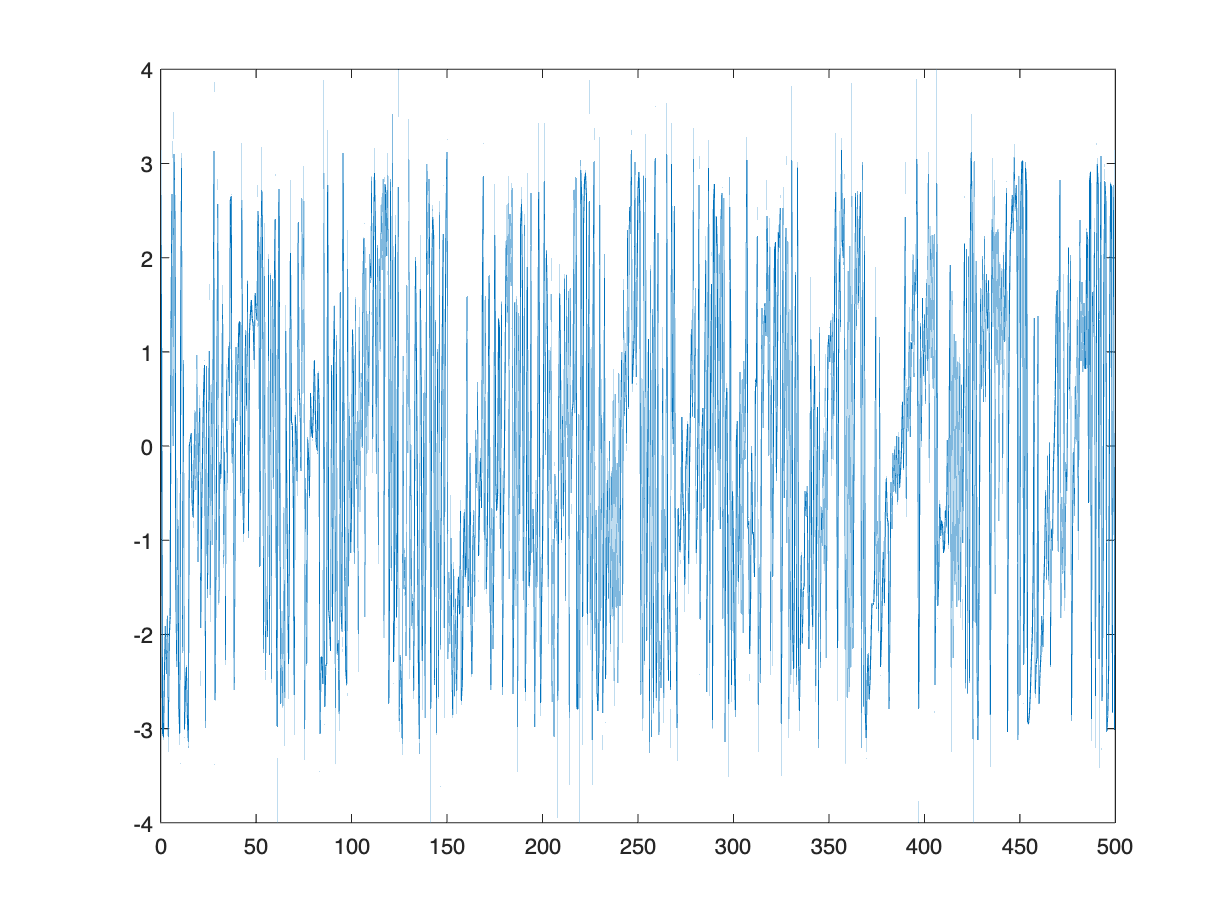

figure;
plot(f, Phi);        % wykres fazowy

Phi(31)

ans = -8.8232e-15

Phi(55)

ans = -1.0472

Phi(167)

ans = 0.4488

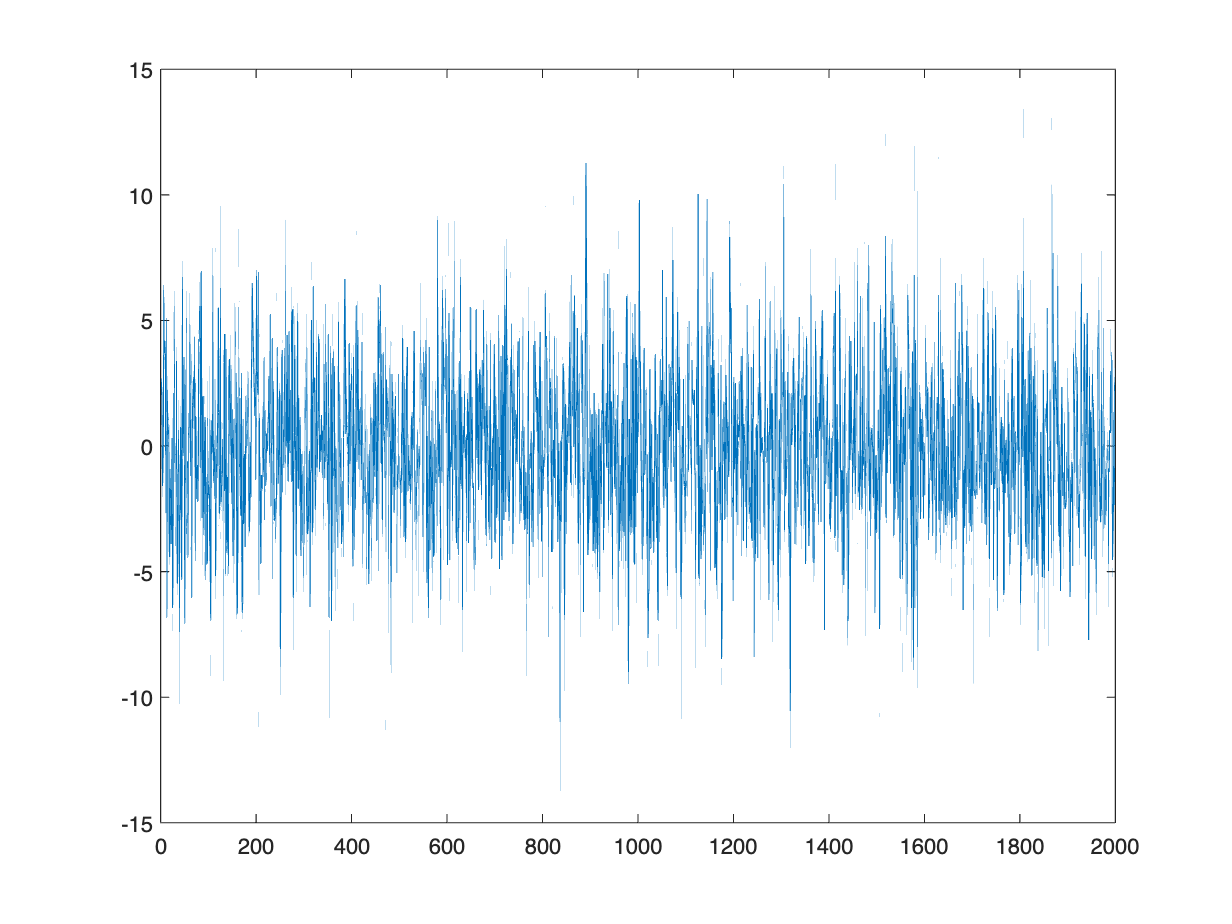

noise = 3 * randn(size(x));

noised_x = x + noise;
plot(noised_x);

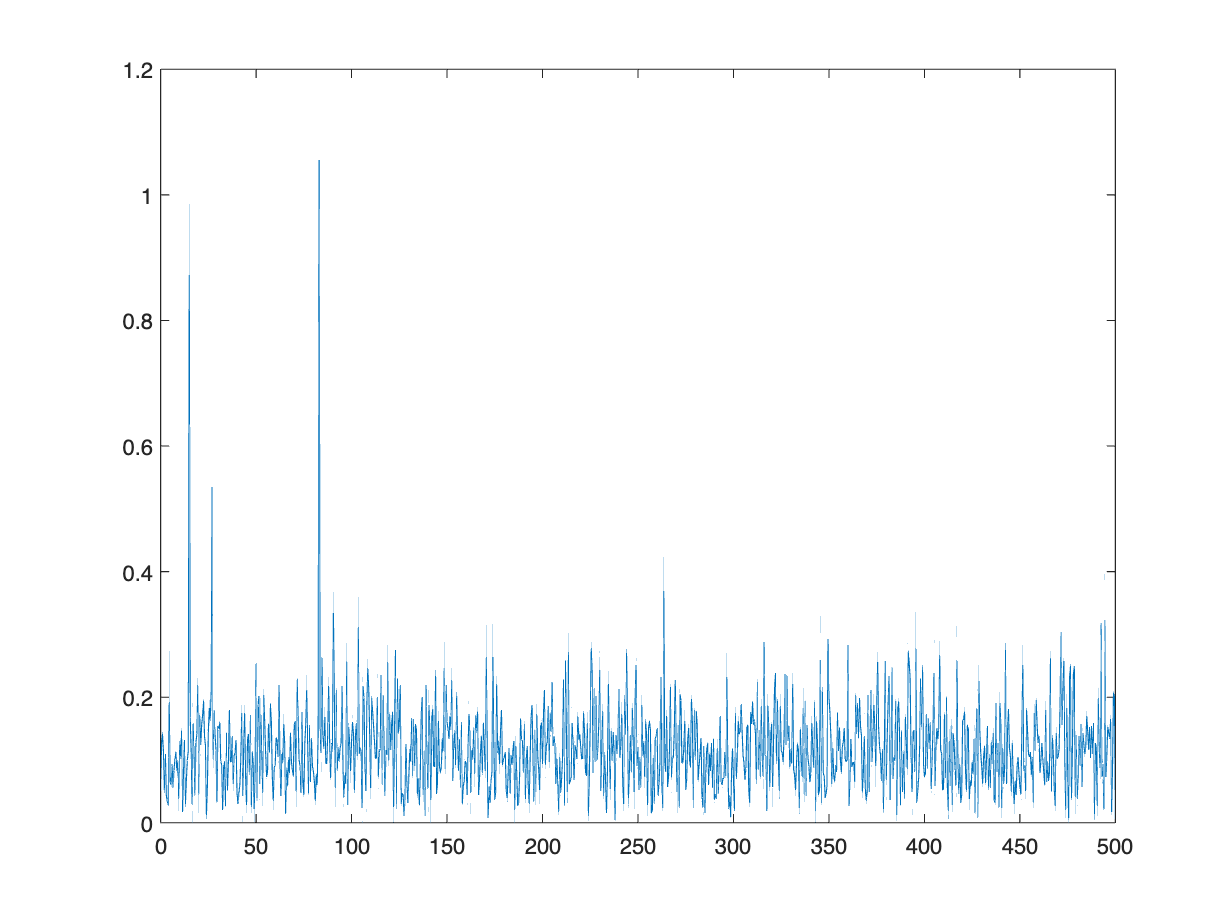

Y_noised = fft(noised_x);     % transformata Fouriera

Amp_noised = abs(Y_noised);     % amplituda sygnału
Amp_noised = Amp_noised/L;        % normalizacja amplitudy

Amp_noised = Amp_noised(1:L/2+1); % wycięcie istotnej części spektrum
Amp_noised(2:end-1) = 2*Amp_noised(2:end-1);

Phi_noised = angle(Y_noised);   % faza sygnału
Phi_noised = Phi_noised(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp_noised);        % wykres amplitudowy

[top_values_noised, indices_noised] = maxk(Amp_noised, 3)

top_values_noised =     1.0551    0.8721    0.5343


indices_noised =    167    31    55


f_top_values_noised = [];
for index = indices_noised
    f_top_values_noised = [f_top_values_noised f(index)];
end

f_top_values_noised

f_top_values_noised =     83    15    27


Na podstawie wykresu amplituda wynosi 

- A = `0,987` dla f =15 Hz

- A = 0,39 dla f =27 Hz

- A = 0,818 dla f =83 Hz

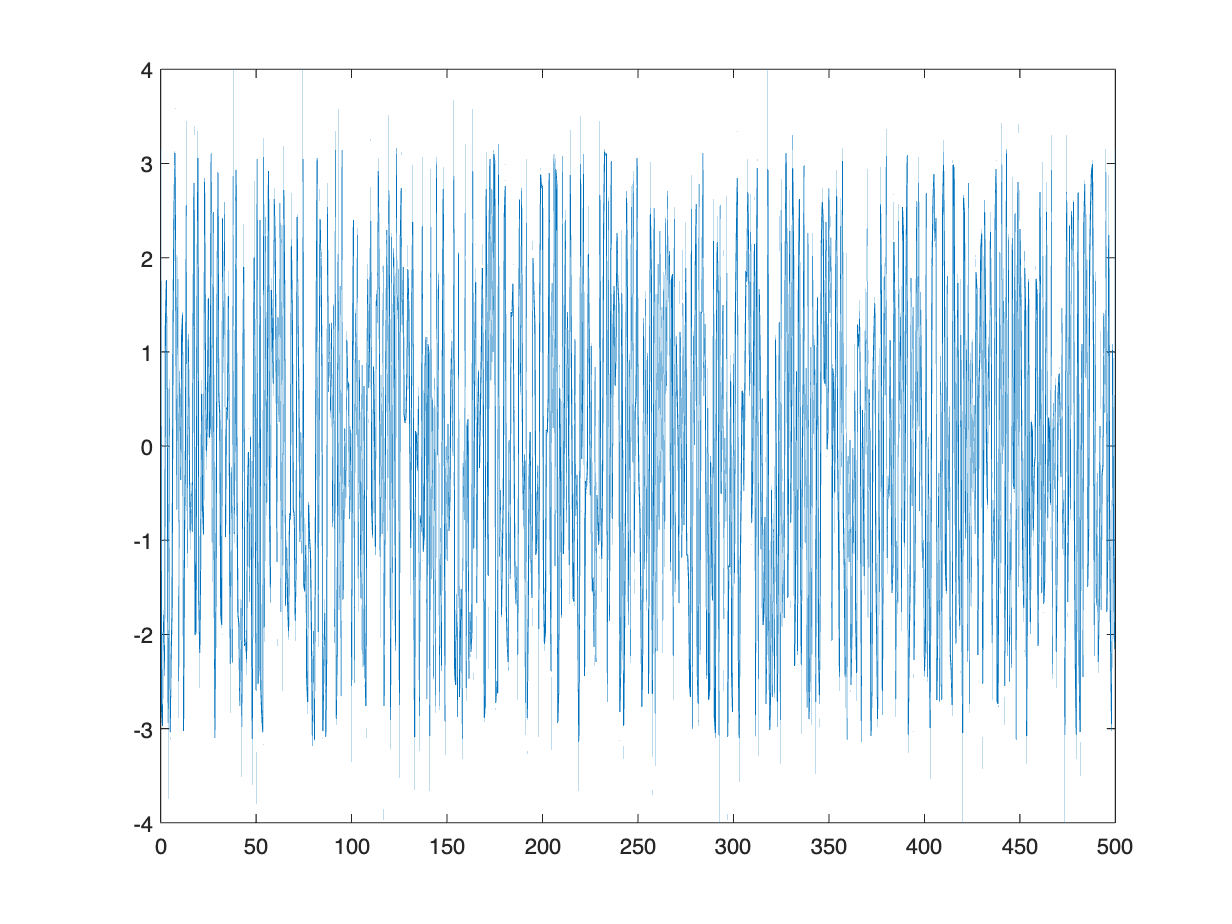

figure;
plot(f, Phi_noised);        % wykres fazowy

Phi_noised(indices_noised)

ans =     0.3415   -0.0079   -1.0204


## Analiza tętna

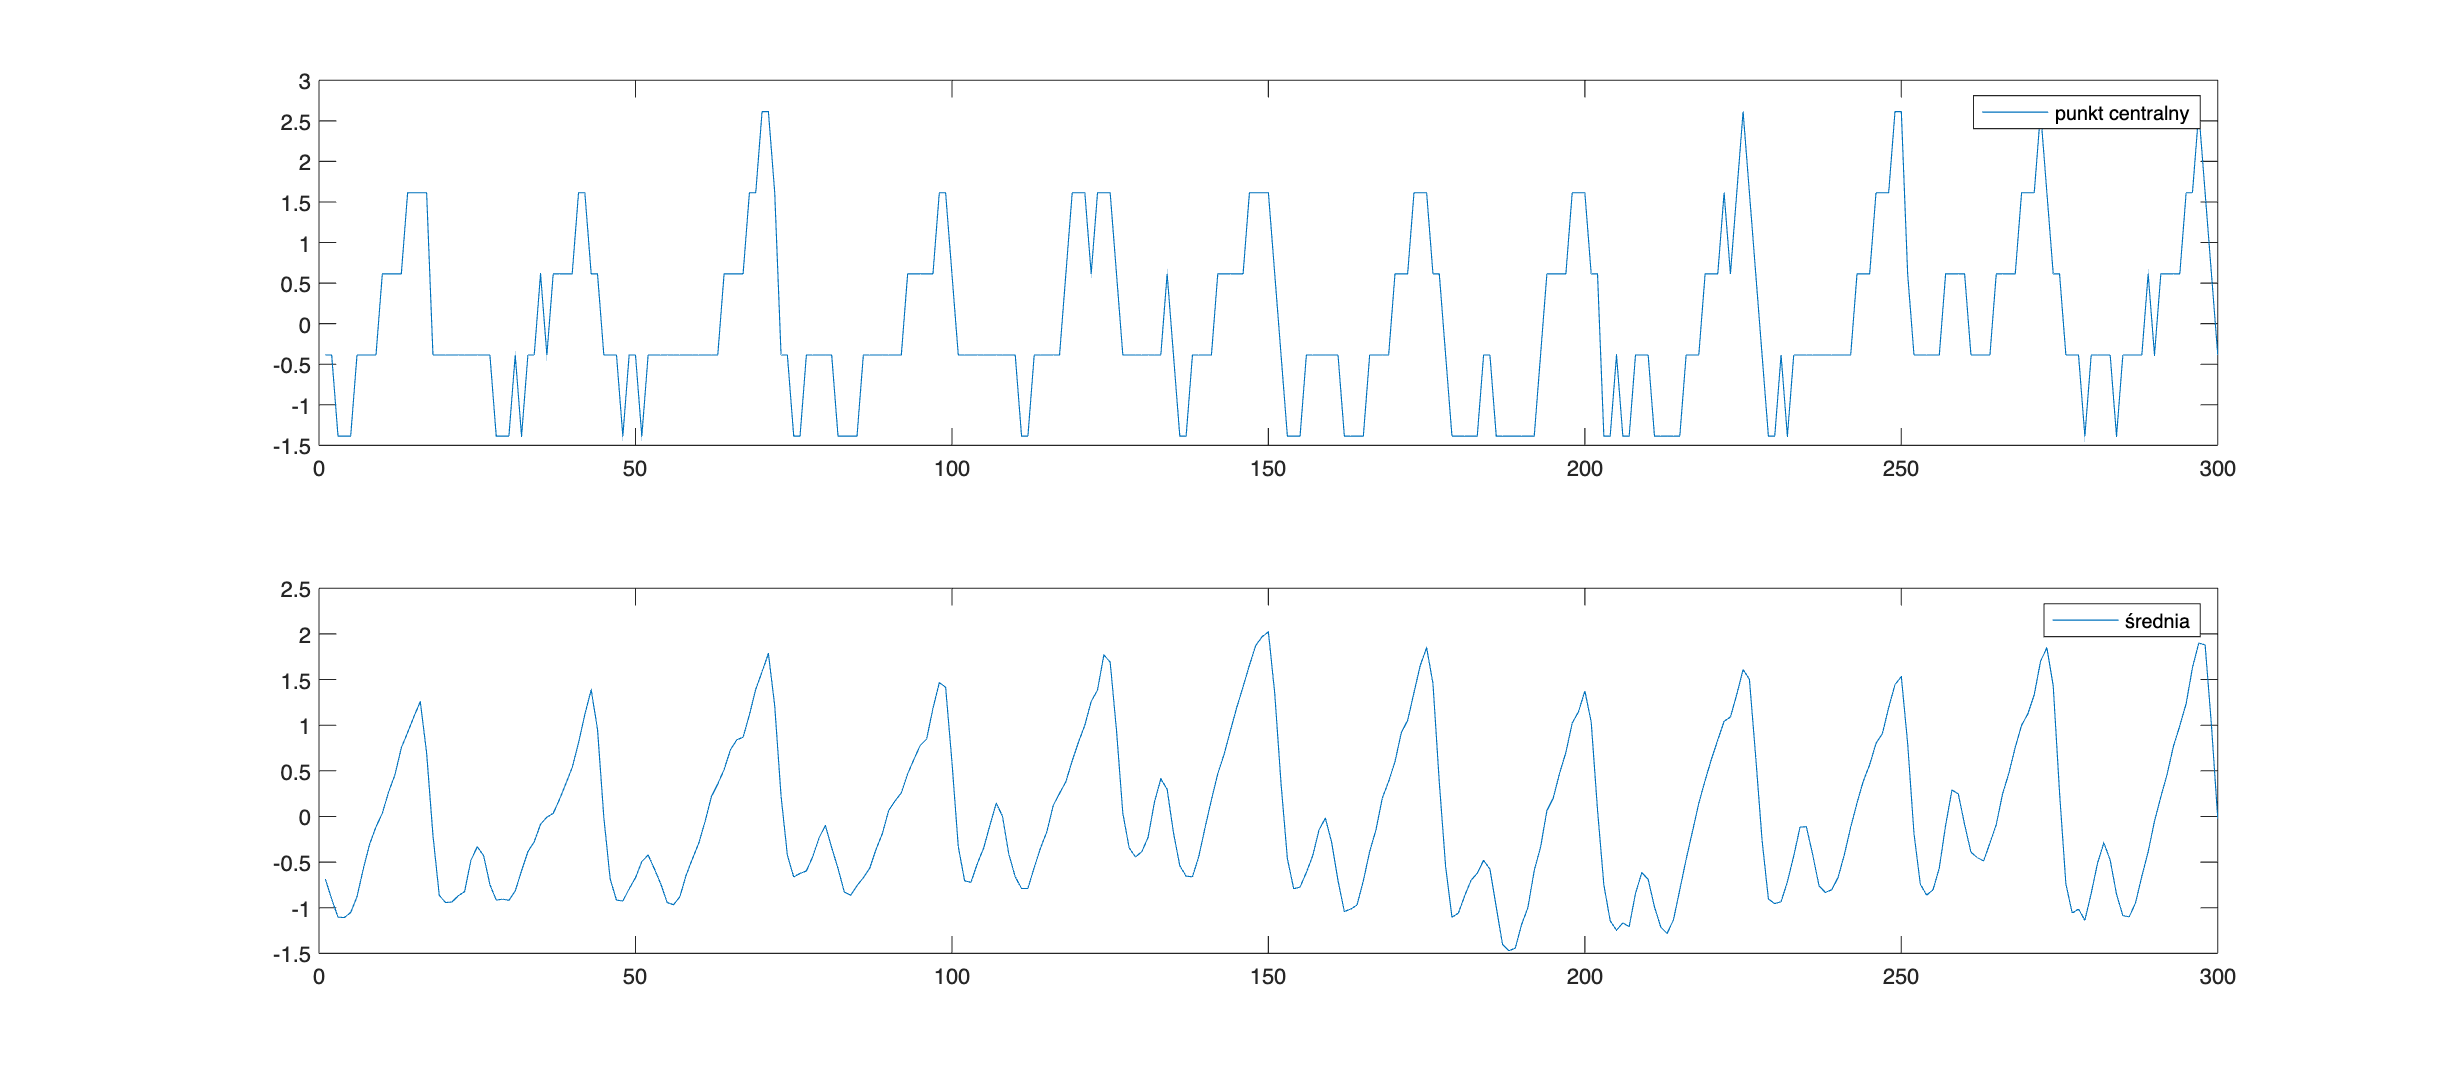

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 300;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    % v = VideoReader('data/movie.mp4');
    v = VideoReader('data/movie_4.MOV');
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);


h = figure();
set(h,'Units','normalized','Position',[0 0 1 .7]); 
subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny')
subplot(2,1,2);
plot(br(2,:));
legend('średnia');

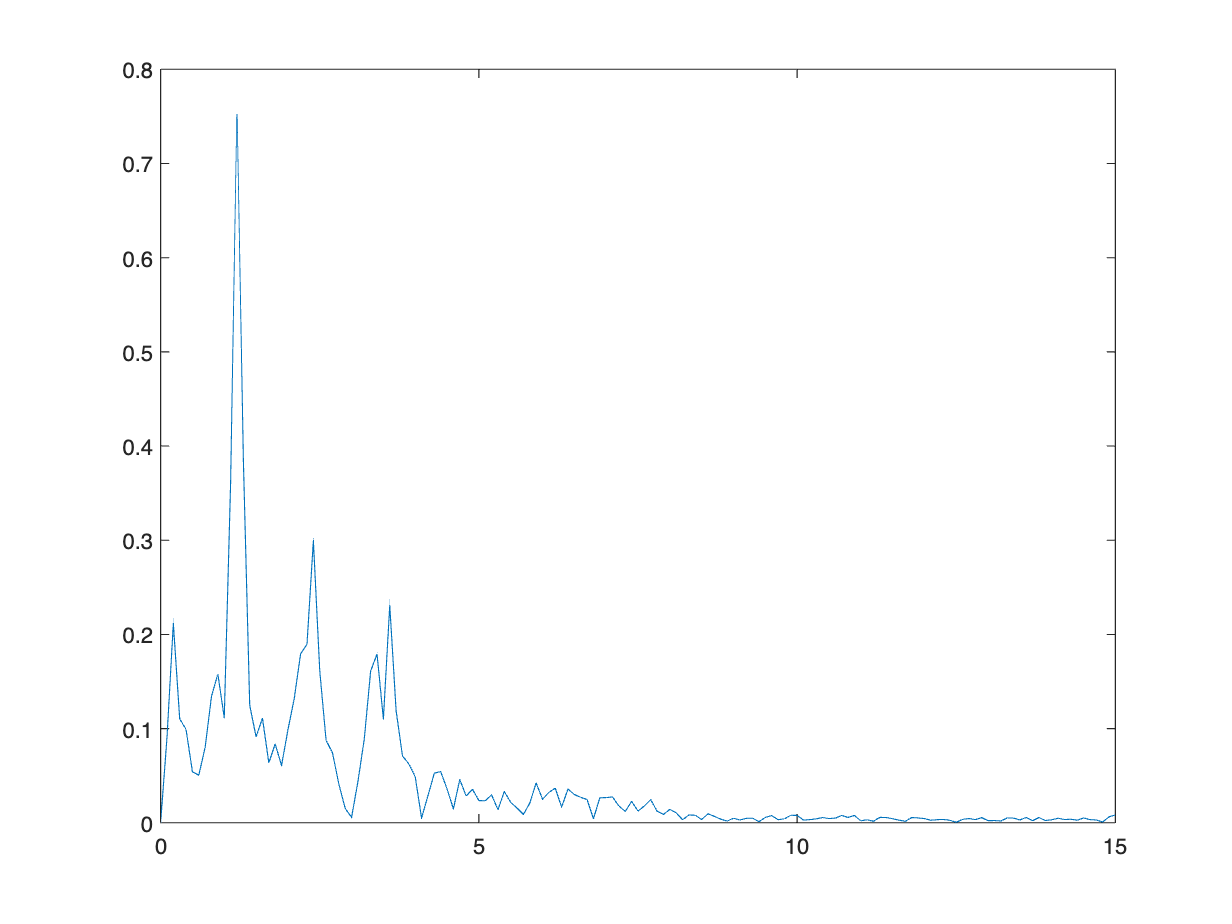

Fs = 30;     % Częstotliwość próbkowania [Hz]
T = 1/Fs;      % Okres próbkowania [s]
L = 300;      % Długość sygnału (liczba próbek)
t = (0:L-1)*T; % Podstawa czasu

Y = fft(br(2,:));     % transformata Fouriera

Amp = abs(Y);     % amplituda sygnału
Amp = Amp/L;        % normalizacja amplitudy

Amp = Amp(1:L/2+1); % wycięcie istotnej części spektrum
Amp(2:end-1) = 2*Amp(2:end-1);

Phi = angle(Y);   % faza sygnału
Phi = Phi(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);        % wykres amplitudowy

[max_value, index] = max(Amp)

max_value = 0.7527

index = 13

pulse_f = f(index)

pulse_f = 1.2000

pulse = pulse_f * 60

pulse = 72.0000

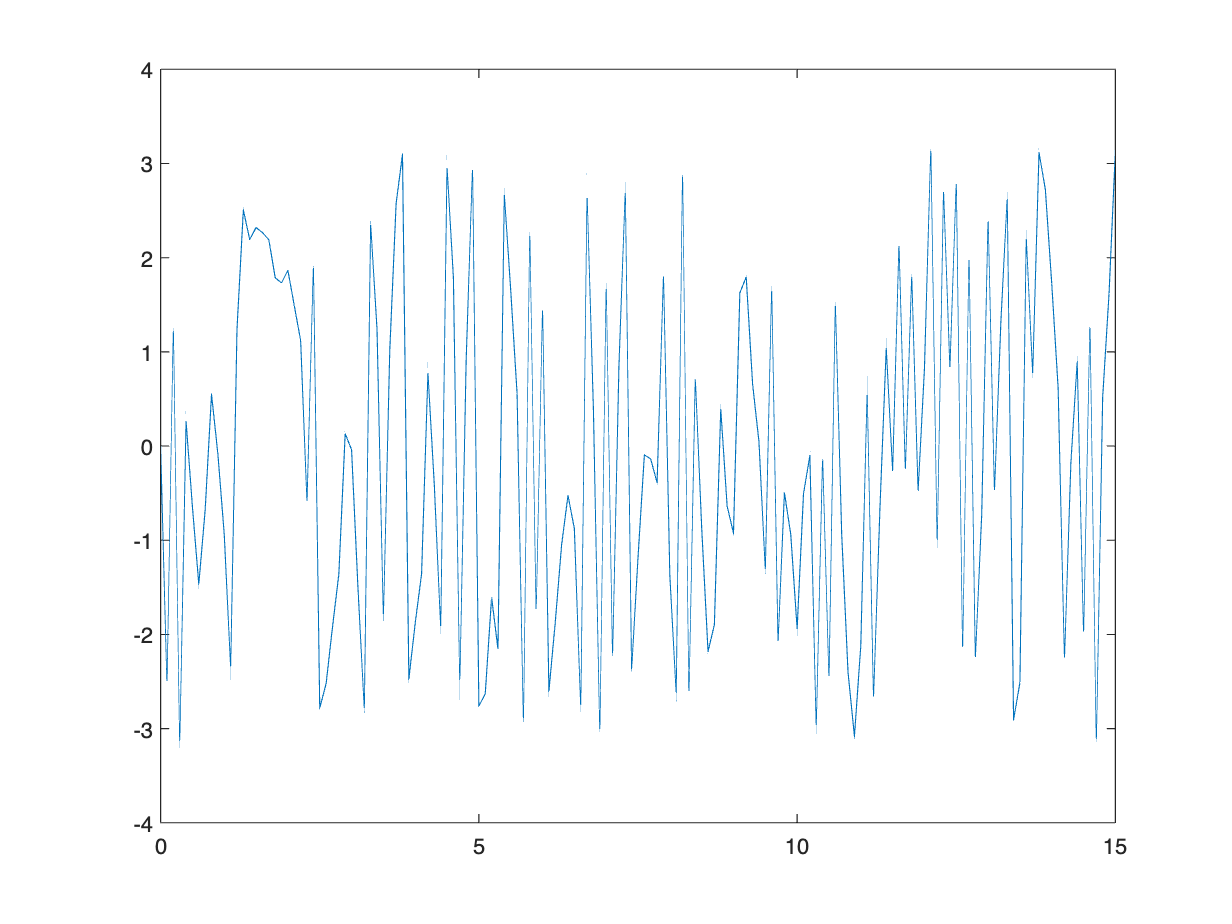


figure;
plot(f, Phi);        % wykres fazowy